# Vector Part 1:

## Vector and Basic Operation of Vector

### Code Exercise (02_01)

> Three methods for creating vectors.

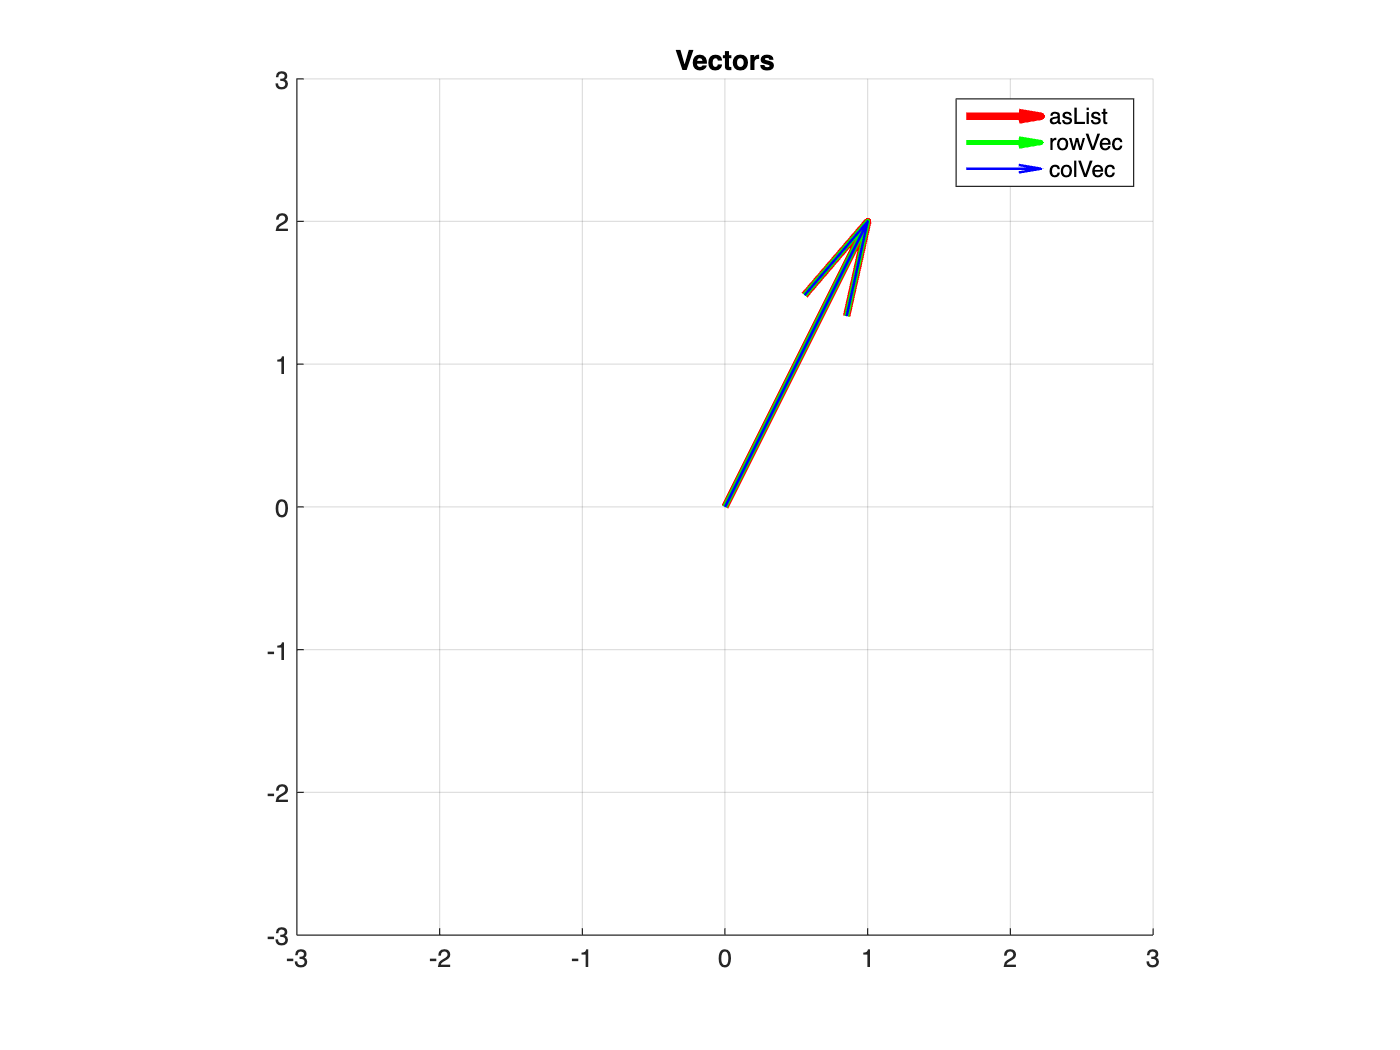

clear; close all; clc;

% Creating a vector as a MATLAB list
asList = [1, 2];

% Creating a row vector
rowVec = [1, 2]; % row

% Creating a column vector
colVec = [1; 2]; % column

% Plotting the vectors using quiver
figure;
hold on;

% To prevent overlap, ther is a 0.1 offset in the starting points of the vectors.
quiver(0, 0, asList(1), asList(2), 'r', 'LineWidth', 3, AutoScale='off', MaxHeadSize=1);
quiver(0, 0, rowVec(1), rowVec(2), 'g', LineWidth=2, AutoScale='off', MaxHeadSize=1);
quiver(0, 0, colVec(1), colVec(2), 'b', LineWidth=1, AutoScale='off', MaxHeadSize=1);

% Set axes properties
axis equal;
xlim([-3, 3]);
ylim([-3, 3]);

% Show grid
grid on;

% Title for the visualization
title('Vectors');

% Legend for vectors
legend('asList', 'rowVec', 'colVec');

### Code Exercise (02_02)

> Generate vectors with different reference points.

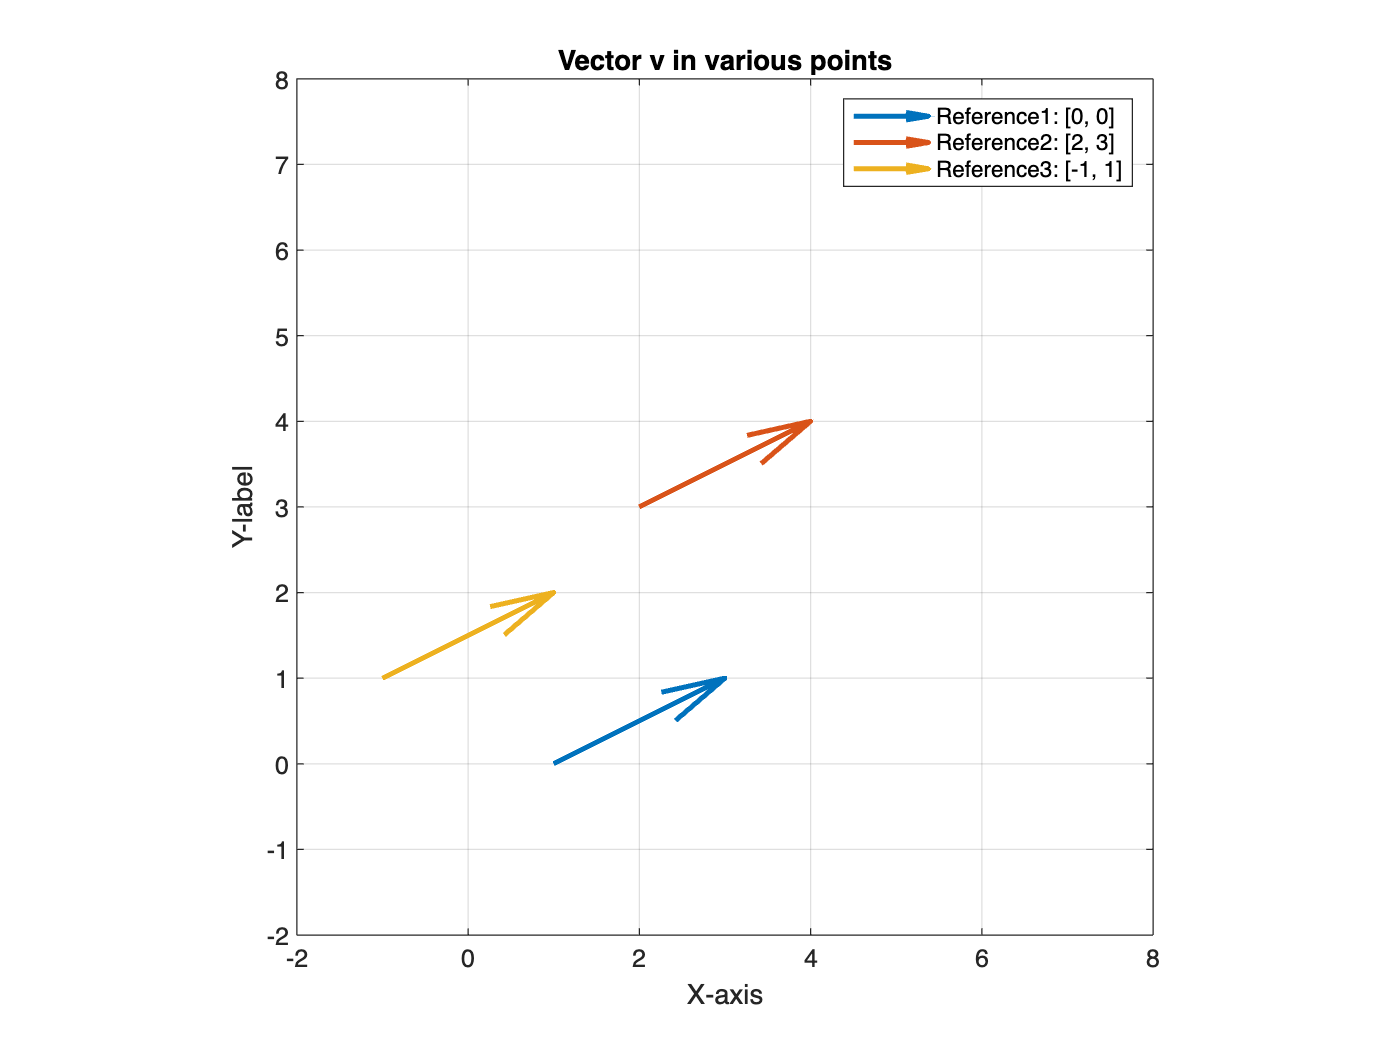

close all; clear; clc;

% Define the vector
v = [2, 1];


% Define three different reference points
reference_points = [1, 0; 2, 3; -1, 1];

% Create a figure
figure;

% Plot the vector with each reference point
for i = 1:size(reference_points, 1)
    quiver(reference_points(i, 1), reference_points(i, 2), v(1), v(2), ...
        LineWidth=2, AutoScale="off", MaxHeadSize=2);
    hold on;
end

% Set axes properties
axis equal;
xlim([-2, 8]);
ylim([-2, 8]);

% Show grid
grid on;

% Title for the visualizstion
title('Vector v in various points');

% Axes labels
xlabel('X-axis');
ylabel('Y-label');

% Legend for vectors with different reference points
legend('Reference1: [0, 0]', 'Reference2: [2, 3]', 'Reference3: [-1, 1]');

### Code Exercise (02_03)

> Addition between two vector.

close all; clear; clc;

%% Adding Vectors

% Using 2D vectors here instead of 3D vectors in the book to facilitate
% visualization
v = [1, 2];
w = [4, -6];
vPlusW = v + w;

% print out all three vectors
disp('v:');

v:


disp(v);

     1     2



disp('w:');

w:


disp(w);

     4    -6



disp('vPlusW:');

vPlusW:


disp(vPlusW);

     5    -4



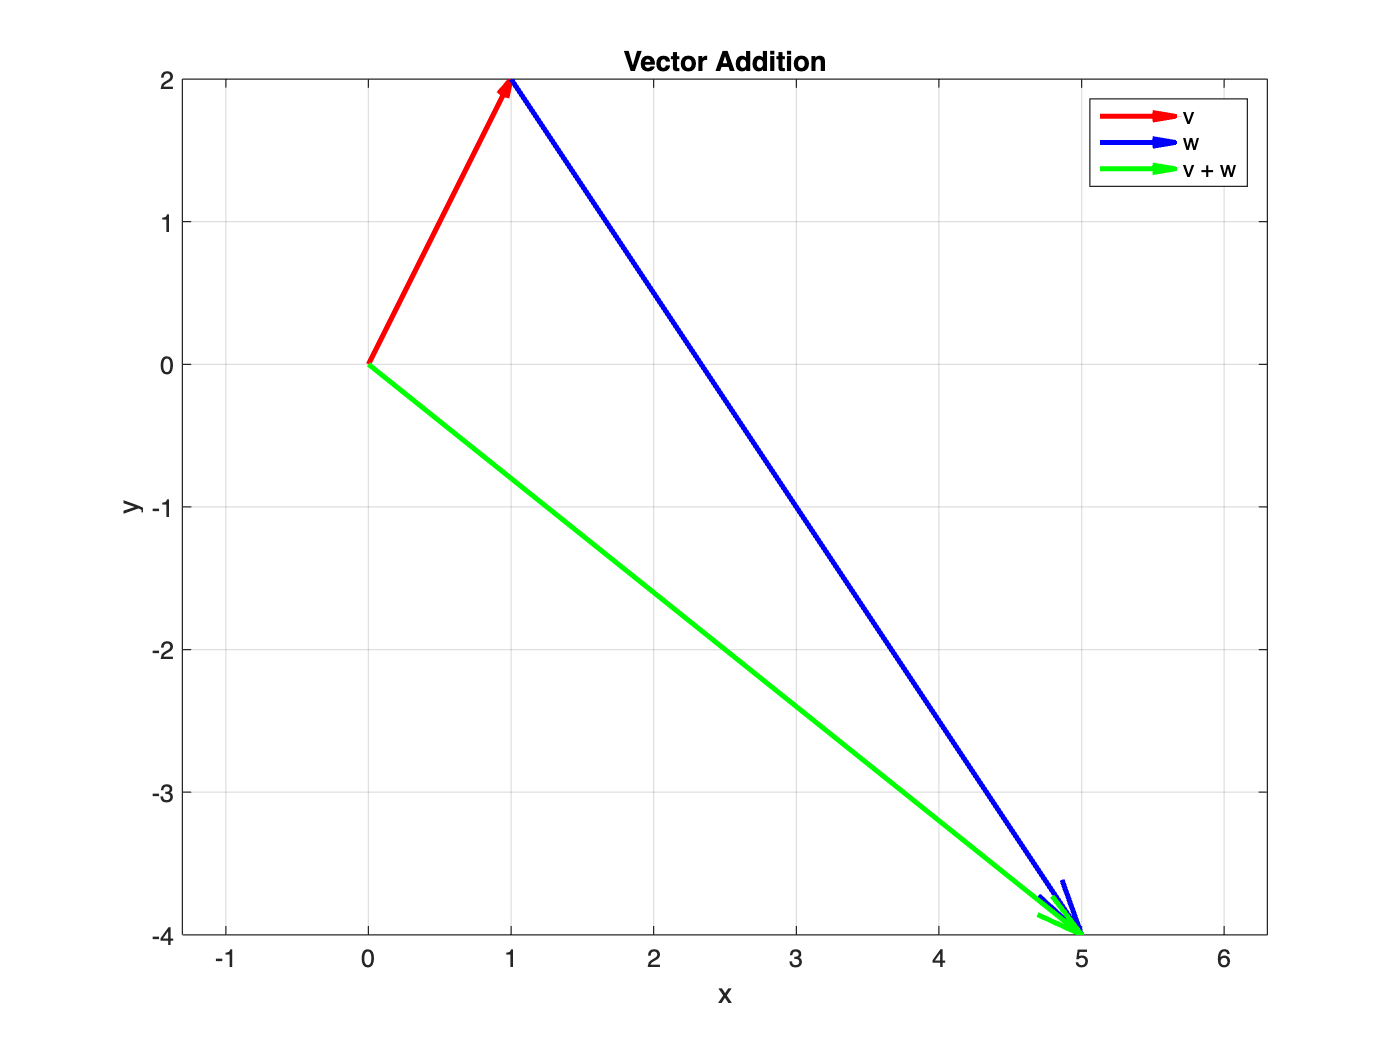


% Plot vectors
quiver(0, 0, v(1), v(2), 0, 'r', LineWidth=2);
hold on;
quiver(v(1), v(2), w(1), w(2), 0, 'b', LineWidth=2);
quiver(0, 0, vPlusW(1), vPlusW(2), 0, 'g', LineWidth=2);
hold off;

axis equal;
xlabel('x');
ylabel('y');
title('Vector Addition');
legend('v', 'w', 'v + w');
grid on;